# Regression LSTM Neural Network for CI Impedance Sensing

## Create the Array of Layers

layers = [
    sequenceInputLayer(1,"Name","sequence")
    lstmLayer(100,"Name","lstm","OutputMode","sequence")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];

## Prepare Training/Validation Data

XTrain = [trial4.Z_bias; trial7.Z_bias];
YTrain = [trial4.A; trial7.A];

XValidation = trial6.Z_bias;
YValidation = trial6.A;

% XTrain = [trial4.Z; trial7.Z];
% YTrain = [trial4.A; trial7.A];
% 
% XValidation = trial6.Z;
% YValidation = trial6.A;

## Options

max_epochs = 40;
mini_batch_size = 1;
gradient_threshold = 1.5;

options = trainingOptions('adam', ...
    'MaxEpochs',max_epochs, ...
    'MiniBatchSize',mini_batch_size, ...
    'LearnRateSchedule',"piecewise", ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency', 25, ...
    'ValidationPatience', 2, ...
    'GradientThreshold',gradient_threshold, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train

net = trainNetwork(XTrain, YTrain, layers, options);

## Test Prediction

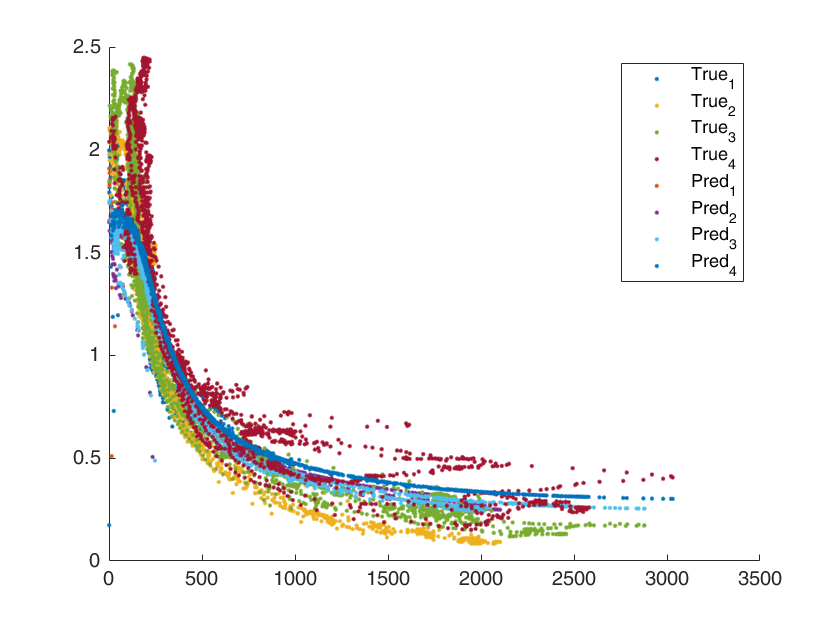

YPred = predict(net, XValidation);

figure; hold on
for ii=1:length(XValidation)
    h_true(ii) = scatter(XValidation{ii}, YValidation{ii}, '.');
    h_pred(ii) = scatter(XValidation{ii}, YPred{ii}, '.');
end
legend([h_true h_pred], {'True_1', 'True_2', 'True_3', 'True_4', 'Pred_1', 'Pred_2', 'Pred_3', 'Pred_4'})
hold off

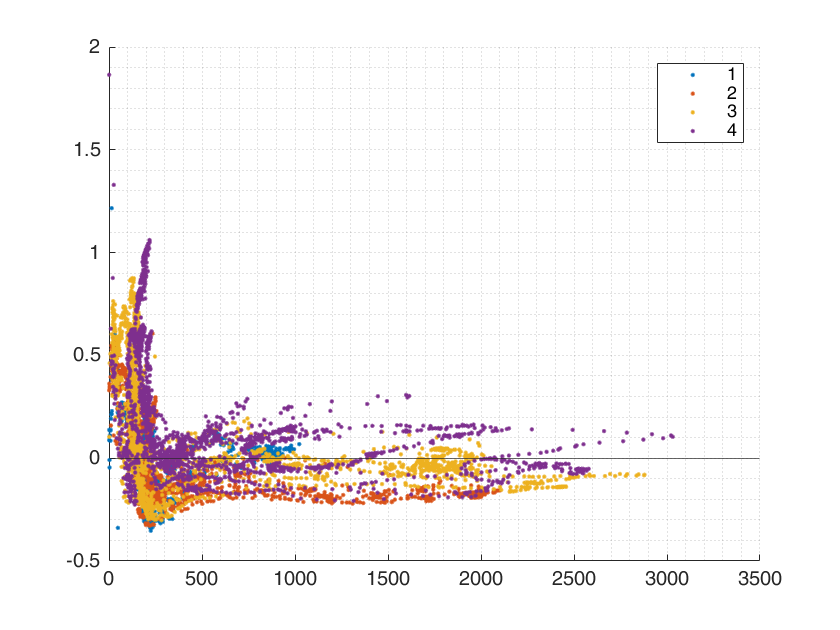


figure; hold on
for ii=1:4
    scatter(XValidation{ii}, YValidation{ii}-YPred{ii}, '.')
end
yline(0);
grid minor
legend('1','2','3','4')

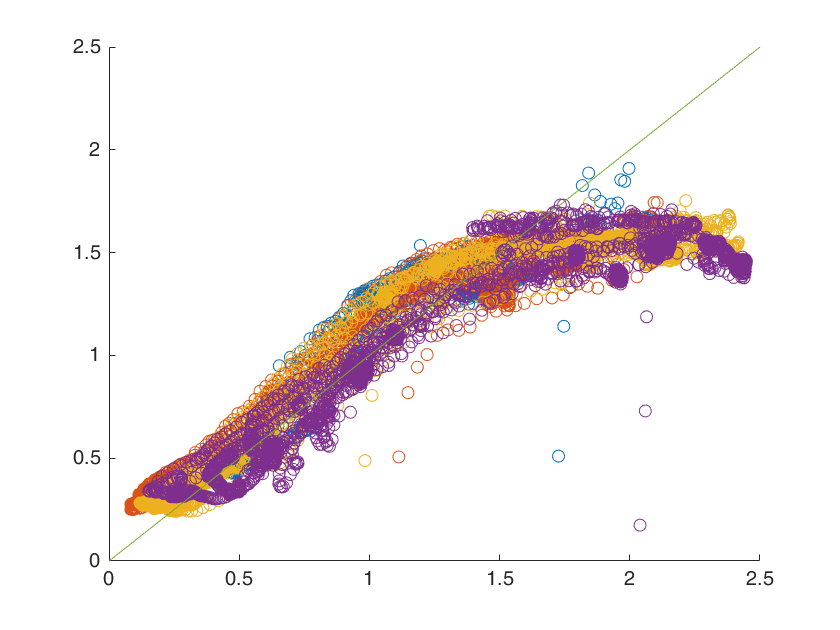


figure; hold on
for ii=1:length(XValidation)
    scatter(YValidation{ii},YPred{ii})
end
plot([0 2.5],[0 2.5])
hold off

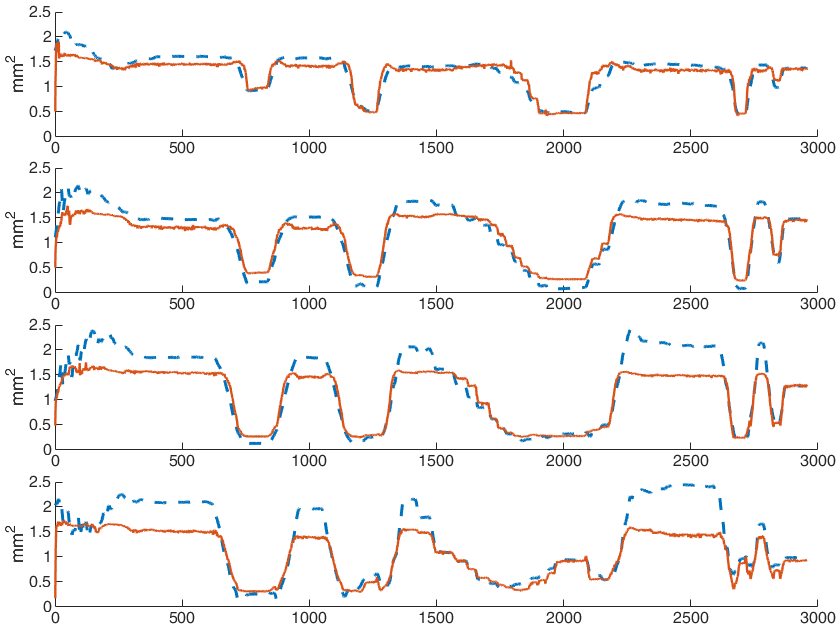


figure;
for ii=1:length(XValidation)
    ax(ii) = subplotXmanyY_er(4,1,ii);
    hold on
    plot(YValidation{ii}, '--', 'LineWidth',1.5)
    plot(YPred{ii},'LineWidth',1.2)
    ylabel('mm^2')
    ylim([0 2.5])
end
linkaxes(ax,'x')
hold off